% This is the .m file produced by Main.mlx
load('CancerDriverGenesGBM_20240621_222151.mat')

GeneralKnownGenesTable = readtable('general_driver_list.csv', 'ReadVariableNames', false);
GeneralKnownGenes = GeneralKnownGenesTable.Var1;

knownGenesForSpecTumor = readtable('Cancer_driver_genes_in_GBM.xlsx');
knownGenesForSpecTumor = table2cell(knownGenesForSpecTumor);

geneNames = mutMatrix.Properties.RowNames;

numSamples = length(rankForSamples);
maxK = 10;
results = zeros(maxK, 5);

for k = 1:maxK
    countCategories = zeros(1, 5); 
    
    for isample = 1:numSamples
        genesForSample = rankForSamples{isample};
        
        if length(genesForSample) < k
            countCategories(1) = countCategories(1) + 1;
        else
            gene = genesForSample{k, 1};
            isCancerDriver = ismember(gene, knownGenesForSpecTumor);
            if ~any(strcmp(geneNames, gene))
                mutFreq = 0;
            else
                mutFreq = sum(mutMatrix{gene, :}) / numSamples;
            end
            
            if isCancerDriver
                if mutFreq < 0.05
                    % isCancerDriver = 1，mutFreq < 5%
                    countCategories(2) = countCategories(2) + 1;
                else
                    % isCancerDriver = 1，mutFreq > 5%
                    countCategories(4) = countCategories(4) + 1;
                end
            else
                if mutFreq < 0.05
                    % isCancerDriver = 0，mutFreq < 5%
                    countCategories(3) = countCategories(3) + 1;
                else
                    % isCancerDriver = 0，mutFreq > 5%
                    countCategories(5) = countCategories(5) + 1;
                end
            end
        end
    end
    
    total = sum(countCategories);
    results(k, :) = countCategories / total;
end

## Plot

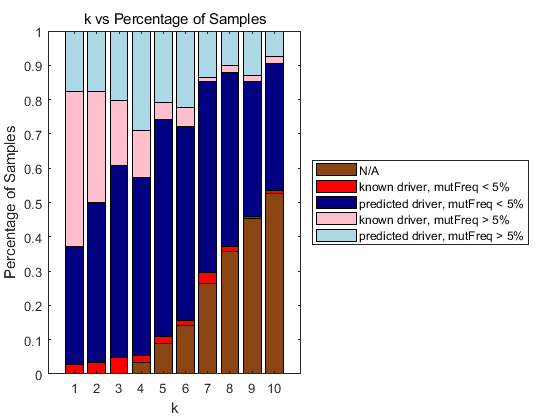

figure;

adjustedResults = results(:, [1, 2, 3, 4, 5]);

b = bar(adjustedResults, 'stacked');
xlabel('k');
ylabel('Percentage of Samples');
title('k vs Percentage of Samples');


customColors = [
    139/255, 69/255, 19/255;  % for 'NA'
    1, 0, 0;                  % for 'Cancer driver, mutFreq < 5%'
    0, 0, 0.5;                % for 'Not cancer driver, mutFreq < 5%'
    1, 0.75, 0.8;             % for 'Cancer driver, mutFreq > 5%'
    0.68, 0.85, 0.9;          % for 'Not cancer driver, mutFreq > 5%'
];

for i = 1:length(b)
    b(i).FaceColor = 'flat';
    b(i).CData = repmat(customColors(i, :), length(b(i).YData), 1);
end

legend({'N/A', ...
    'known driver, mutFreq < 5%', 'predicted driver, mutFreq < 5%', ...
    'known driver, mutFreq > 5%', 'predicted driver, mutFreq > 5%'}, ...
    'Location', 'eastoutside');

## Common genes

% topAct = 8;
% geneFrequency = containers.Map;
% 
% for i = 1:length(rankForSamples)
%     sampleGenes = rankForSamples{i}(:, 1);
% 
%     numGenesToConsider = min(topAct, length(sampleGenes));
% 
%     for j = 1:numGenesToConsider
%         gene = sampleGenes{j};
%         if isKey(geneFrequency, gene)
%             geneFrequency(gene) = geneFrequency(gene) + 1;
%         else
%             geneFrequency(gene) = 1;
%         end
%     end
% end
% 
% filteredGeneFrequency = containers.Map;
% for k = 1:length(knownGenesForSpecTumor)
%     gene = knownGenesForSpecTumor{k};
%     if isKey(geneFrequency, gene)
%         filteredGeneFrequency(gene) = geneFrequency(gene);
%     else
%         filteredGeneFrequency(gene) = 0;
%     end
% end
% 
% geneList = keys(filteredGeneFrequency);
% freqList = values(filteredGeneFrequency);
% resultArray = [geneList', num2cell(cell2mat(freqList)')];
% sortedResultArray = sortrows(resultArray, -2);
% 
% sortedResultArray;